Both transmitters transmit at 10 GHz, and we model their signal bandwidth as 400 MHz. These are the operating parameters of the receive radio.

fc = 10e9;
fsBaseband = 400e6;

## Transmit Signals

The signal of interest is an FM audio signal. We are using this kind of signal to demonstrate the transmission of audio data, but any kind of waveform could be used.

We read the audio signal from a default matlab audio file and create the signal of interest using the FM Modulator.

[y, fsAudio] = audioread('guitartune.wav');
modulator   = comm.FMModulator(SampleRate=fsBaseband,FrequencyDeviation=fsBaseband/3);
soi = modulator(y);

We create a complex noise signal to create interference across the entire bandwidth.

interference = randn(length(soi),1,like=1i);

We compare the transmit and receive spectrums in the frequency domain.

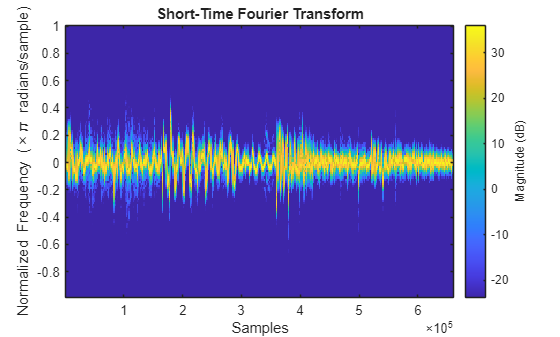

stft(soi);

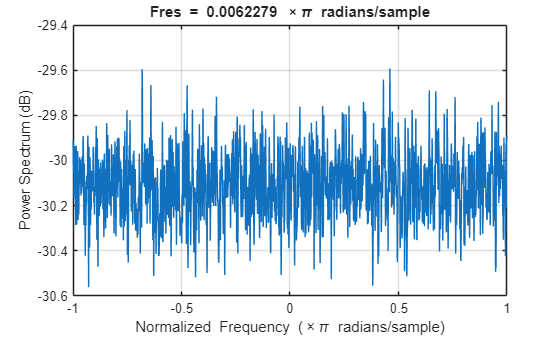

pspectrum(interference);

## Transmit Antennas

The transmitter transmitting the signal of interest and the transmitter transmitting the interference are both modelled as transmitting with an isotropic radiation pattern.

soiTransmitter = phased.IsotropicAntennaElement;
interferenceTransmitter = phased.IsotropicAntennaElement;

The antenna pattern of an isotropic element is uniform in all directions.

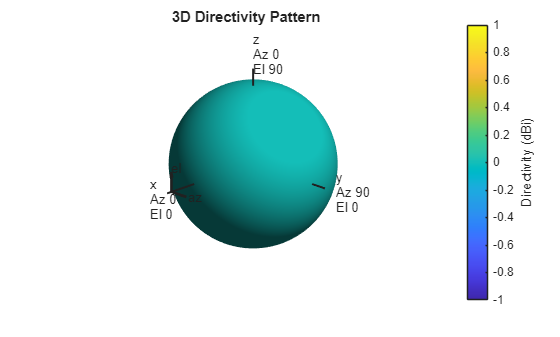

soiTransmitter.pattern(fc);

Use the phased.Radiator to radiate the transmitted signals.

soiRadiator = phased.Radiator(Sensor=soiTransmitter,OperatingFrequency=fc);
intRadiator = phased.Radiator(Sensor=interferenceTransmitter,OperatingFrequency=fc);

Set the initial position of the signal of interest and the interferer.

soipos = [5;2;-3];
intpos = [5;-2;2];

## Signal Propagation

Use a free space propagation model.

soiChannel = phased.FreeSpace(OperatingFrequency=fc,SampleRate=fsBaseband);
intChannel = phased.FreeSpace(OperatingFrequency=fc,SampleRate=fsBaseband);

## Receive Antenna Array

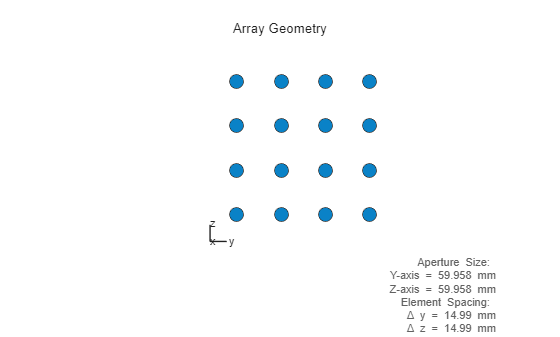

spacing = freq2wavelen(fc)/2;
rxArray = phased.URA(Size=[4 4],ElementSpacing=[spacing spacing]);
viewArray(rxArray);

Use the phased.Collector to receive the signal and interference.

rxCollector = phased.Collector(Sensor=rxArray,OperatingFrequency=fc);

The receiver is positioned at the origin.

rxpos = [0;0;0];

## Receive Radio

The radio is modeled with just gain and additive noise. All second order effects are ignored.

receiver = phased.Receiver(Gain=20,NoiseFigure=10,ReferenceTemperature=300,SampleRate=fsBaseband);

## Signal Processing

A MUSIC estimator is created to perform 2D direction of arrival estimation.

music = phased.MUSICEstimator2D(SensorArray=rxArray,OperatingFrequency=fc,AzimuthScanAngles=-90:90,...
    ElevationScanAngles=-90:90,NumSignalsSource="Property",NumSignals=2,DOAOutputPort=true);

An MVDR beamformer is created to beamform the incoming signal.

mvdr = phased.MVDRBeamformer(SensorArray=rxArray,OperatingFrequency=fc,TrainingInputPort=true,...
    DirectionSource="Input port",WeightsOutputPort=true);

## Training Data Collection

We collect an initial dataset with only the interference present to train the MVDR algorithm.

Get the range and angle between the interferer and the receiver.

[intrange,intang] = rangeangle(intpos,rxpos);

Transmit the interfering waveform towards the receiver..

txIntSig = intRadiator(interference,-intang);

Pass the transmit signal through the propagation channel

propInt = intChannel(txIntSig,intpos,rxpos,[0;0;0],[0;0;0]);

Receive the interference signal at the receive array.

collectSig = rxCollector(propInt,intang);

Pass the signal through the receiver.

trainSig = receiver(collectSig);

Estimate the interference DOA. First, set the estimator to only look for one signal.

music.NumSignals = 1;

Apply the estimator.

[~,intdoa] = music(trainSig);

## Data Simulation

Create the simulation control.

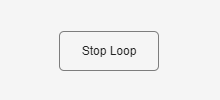

control = SimulationControl();

musicax = axes(figure);

Set the estimator to look for two signals - the signal of interest and the interference.

release(music);
music.NumSignals = 2;

Specify the number of samples to propagate in the loop.

nsamples = 100;
startidx = 1;

Run the data simulation loop collecting signal of interest and interference.

while ~control.StopRequested

Get the next set of samples.

endidx = startidx + nsamples - 1;
if endidx > length(soi)
    startidx = 1;
    endidx = startidx + nsamples;
end

Get the angle of the interferer and signal of interest.

[~,soiang] = rangeangle(soipos,rxpos);
[~,intang] = rangeangle(intpos,rxpos);

Transmit the waveforms towards the receiver.

txSoi = soiRadiator(soi(startidx:endidx),-intang);
txInt = intRadiator(interference(startidx:endidx),-intang);

Pass the signals through the propagation channels.

propSoi = soiChannel(txSoi,soipos,rxpos,[0;0;0],[0;0;0]);
propInt = intChannel(txInt,intpos,rxpos,[0;0;0],[0;0;0]);

Receive the interference signal at the receive array.

collectSig = rxCollector([propInt propSoi],[intang soiang]);

Pass the signal through the receiver.

rxSig = receiver(collectSig);

Apply MUSIC algorithm.

[musicSpec,doa] = music(rxSig);
helperPlotMUSICSpectrum(musicax,music,musicSpec,soiang,intang,'MUSIC Spectrum');

Calculate the signal of interest DOA using the known interference DOA.

[~,intIdx] = min(sum((doa-intdoa).^2,1));
soiIdx = [true true];
soiIdx(intIdx) = false;
soiDoa = doa(:,soiIdx);

Generate the MVDR weights pointing the beamformer towards the signal of interest.

[mvdrsig,wmvdr] = mvdr(rxSig,trainSig,soiDoa);

Enforce plotting.

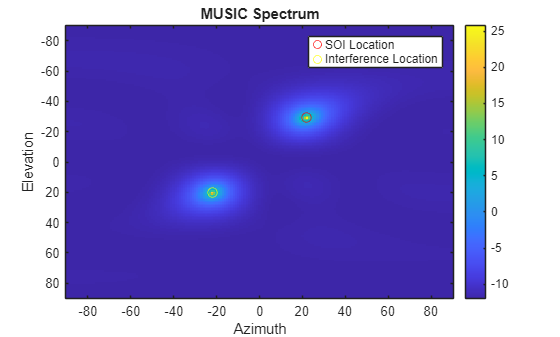

drawnow;
end

## Helper Functions

function helperPlotMUSICSpectrum(ax,musicEstimator,musicSpectrum,soiAoa,intAoa,tstr)
% Plot the 2D MUSIC spectrum with the true angle of arrival

    az = musicEstimator.AzimuthScanAngles;
    el = musicEstimator.ElevationScanAngles;
    imagesc(ax,az,el,mag2db(abs(musicSpectrum)));
    hold(ax, 'on');
    scatter(ax,soiAoa(1,:),soiAoa(2,:),"red",DisplayName='SOI Location',SizeData=50);
    scatter(ax,intAoa(1,:),intAoa(2,:),"yellow",DisplayName='Interference Location',SizeData=50);
    legend(ax);
    colorbar(ax);
    title(ax,tstr);
    xlabel(ax,'Azimuth');
    ylabel(ax,'Elevation');
    hold(ax,'off');
end